states_0 = state_vec_to_struct(zeros(30, 1))

states_0 = struct with fields:
     posn_body: [3×1 double]
      vel_body: [3×1 double]
     quat_body: [1×1 quaternion]
        bias_f: [3×1 double]
    bias_omega: [3×1 double]
       posn_bv: [3×1 double]
       quat_vb: [1×1 quaternion]
      posn_tag: [3×1 double]
      quat_tag: [1×1 quaternion]


states_0.posn_body = [1, 0, 0]';
states_0.vel_body = [0, 1, 0]';
states_0.quat_body = quaternion([0, 0, 0], 'eulerd', 'xyz', 'frame');

states_0.quat_vb = quaternion([0, 0, 45], 'eulerd', 'xyz', 'frame');

states_0.posn_tag = [1, 0, 0]';
states_0.quat_tag = quaternion([1, 0, 0, 0]);

v_states_0 = state_struct_to_vec(states_0);

tab_states_0 = states_structs_to_tab(states_0);
tab_tags_0 = tags_body_to_world(tab_states_0);

tab_tags_0.posn_tag

ans =     1.7071   -0.7071         0


quat2eul(tab_tags_0.quat_tag, 'xyz') * 180 / pi

ans =          0         0   45.0000


f = [0, 0, 0];
omega = [0.2, 0, pi/6];
%omega = [0 0 0];

u = [f(:); omega(:)];

t_0 = 0;
t_end = 10;
dt = 1/15;

iterations = (t_end - t_0) / dt;
mat_u = repelem(u, 1, iterations);

mat_u(3, 1:end/2) = 1;
mat_u(3, end/2:end) = -2;

use_ode45 = true;

tic
[t_out, structs_states, states_out] = sim_state_transition(v_states_0, mat_u, dt, use_ode45);
elapsed_time = toc;
fprintf("Max prediction speed: %.2fHz", size(mat_u, 2)/elapsed_time)

Max prediction speed: 6.71Hz

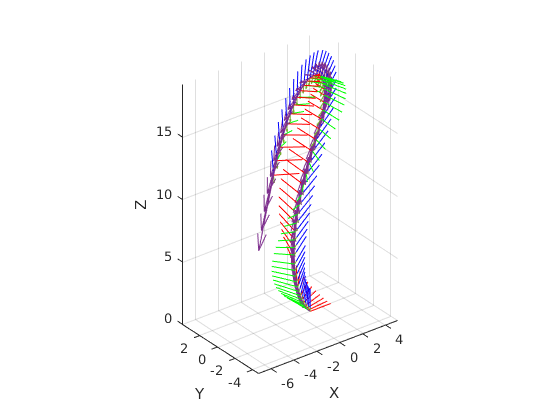


tab_states = states_structs_to_tab(structs_states);

plot_points = 50;

% Ceiling
if plot_points > length(structs_states)
    plot_points = length(structs_states);
end

% Generate the indices
% We don't want to plot the final point
plot_indices = round(linspace(1, length(structs_states) - 1, plot_points));

viz_state_transition(structs_states(plot_indices), mat_u(:, plot_indices));

tab_tags = tags_body_to_world(tab_states);

tab_tags.posn_tag

ans =     1.7071   -0.7071         0
    1.7083   -0.7071   -0.0004
    1.7094   -0.7071   -0.0009
    1.7106   -0.7070   -0.0013
    1.7118   -0.7069   -0.0018
    1.7129   -0.7068   -0.0022
    1.7141   -0.7066   -0.0027
    1.7152   -0.7065   -0.0031
    1.7163   -0.7062   -0.0035
    1.7175   -0.7060   -0.0040


compact(tab_tags.quat_tag)

ans =     0.9239         0         0    0.3827
    0.9239    0.0000         0    0.3827
    0.9239    0.0000         0    0.3827
    0.9239    0.0000         0    0.3827
    0.9239    0.0000   -0.0000    0.3827
    0.9239   -0.0000   -0.0000    0.3827
    0.9239   -0.0000   -0.0000    0.3827
    0.9239    0.0000   -0.0000    0.3827
    0.9239    0.0000         0    0.3827
    0.9239    0.0000   -0.0000    0.3827


quat2eul(tab_tags.quat_tag(end), 'xyz') * 180 / pi

ans =     0.0000    0.0000   45.0000
